Problem 3.102 in PS07

Use MATLAB to repeat Example 3.7 for N=50 and (a) M = 12, (b) M=5, and (c) M=20

Example 3.7: Building A Square Wave From DTFS Coefficients

The contribution of each term to the square wave may be illustrated by defining the partial-sum approximation to x[n] in Eq. (3.17) as 

    xhat_J[n] = sum(k==0 to J) [ B[k] cos(k Omega_0 n), where J<= N/2. This approximation contains the first 2J +1 terms centered on k=0 in Eq. (3.10). Assume a square wave has period N=50, M=12. Evaluate on period of the Jth term in Eq. (3.18) and 2J+1 term approximation xhat_J[n] for J = 1,3,5,23,25. 

From page 208-210: 

Square wave: x[n] = { 1, -M <= n <= M    ;     { 0, M < n < N -M

X[k] = 1/N * (sin(k *pi (2M+1)/N))/(sin(k * pi / N)) for k not equal to 0, +-N, +-2N

= (2M+1)/N for k equal to 0, +-N, +-2N

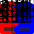

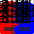

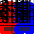

% For J = 1, 3, 5, 23, 25
% (a) M = 12
% (b) M = 5
% (c) M = 20

N = 50; % Constant
n = -25:24; % n is the dependent variable, to be graphed
M_array = [12, 5, 20]; % width of square wave
J_array = [1, 3, 5, 23, 25]; % partial sum limit
    

for mIndex = 1:length(M_array)
    M = M_array(mIndex);
    figure
    for jIndex = 1:length(J_array)
        J = J_array(jIndex);

        subplot(5, 2, 1+2*(jIndex-1));
        stem(n(1:50), DTFS_Coeff(N, M, J)*cos(J*2*pi/N*n(1:50)), 'filled', 'r')
        title('DTFS Term')
        xlabel('n');
        ylabel(sprintf('B[%d]cos(\\omega_0n)', J))
        grid on;
        
        subplot(5, 2, 2+2*(jIndex-1)); 
        stem(n, sum_of_DTFS_Coeffs(N, M, J, n), 'filled', 'b') 
        title('Partial Sum')
        xlabel('n');
        ylabel(sprintf('x̂_{%d}[n]', J))
        grid on;
        sgtitle(sprintf('\\underline{Square Wave From DTFS Coefficients, M=%d: Seth Ricks}', M), 'Interpreter', 'latex'); %Subgraph title
    end
end

N = period, M = width of square wave, k = coefficient number

Function for calculating sum of DTFS terms

function x_n = sum_of_DTFS_Coeffs(N, M, J, n)             
    x_n = zeros(1, length(n));      % initialize output
    
    for k = 0:J
        B_k = DTFS_Coeff(N, M, k);
        x_n = x_n + B_k * cos(k*2*pi/N*n);  % add each term
    end
end

Function for calculating DTFS coefficients

function B_k = DTFS_Coeff(N, M, J)
    if (J == 0)
        x_k = (2*M+1)/N;  % handle intederminate 0/0 term
    else
        x_k = 1/N * sin((J*pi)*(2*M+1)/N) / sin((J*pi)/N);
    end

    if (J == 0 || J == N/2)
        B_k = x_k;
    else
        B_k = 2 * x_k;
    end
end